## Walkthrough with paired single cell RNA-seq and ATAC-seq data of A549 cells

### Load data

addpath('./Data')
load('A549_sciCAR_data.mat');

### Process data and select features

This step includes two aspects: Removing cells and features in low quality and selecting features.

#### Process scRNA-seq data

minCells = 10; minCounts = 500; maxCounts = 9100; 
proData1 = preprocessing(RNA,minCells,minCounts,maxCounts);

processing data:


X1 = proData1.data; Genes = proData1.Features; Cells1 = proData1.Cells;
[~,~,idy1] = intersect(Cells1,RNA.Cells,'stable');
time = time(idy1);

#### Gene selection: if there are experiment conditions (e.g. time series), we select differentially expressed genes by Wilcoxon rank test, we select high variable genes otherwise.

condition = time; system_used = 'Mac'; r = 0.05; fc = 0.1;
id1 = gene_selection(X1,time,system_used,r,fc);
X1 = X1(id1,:); Genes = Genes(id1);

#### Process scATAC-seq data

minCells = 5; minCounts = 200; 
proData2 = preprocessing(ATAC,minCells,minCounts);

processing data:


X2 = proData2.data; Loci = proData2.Features; Cells2 = proData2.Cells;

#### Loci selection (optional): To reduce the dimension of chromatin accessibility profiles, we just focus on near loci of high variable genes. Note: we did not do this step in the paper. If you want to shorten running time, you can uncomment the following steps.

% species = 'human';
% system_used = 'Mac';
% genes_regions = search_gene_loci(Genes,system_used,species);
% bin = 100000;
% genes_nearby_loci = search_nearby_loci(Genes,Loci,Loci,system_used,bin,species);
% [~,~,id2] = intersect(genes_nearby_loci,Loci,'stable');
% X2 = X2(id2,:);
% Loci = Loci(id2);

#### Intersect scRNA-seq and scATAC-seq

[~,index1,index2] = intersect(Cells1,Cells2,'stable');
Cells = Cells1(index1);
time = time(index1);
X1 = X1(:,index1); X2 = X2(:,index2);
c1 = median(X1(X1 ~= 0)); c2 = median(X2(X2 ~= 0));
X2 = X2/c2*c1;
RNA = array2table(X1,'RowNames',Genes,'VariableNames',Cells);
ATAC = array2table(X2,'RowNames',Loci,'VariableNames',Cells);

### Run scAI

K = 2;
alpha = 1; lambda = 100000; gamma = 1; s = 0.25;
result = run_scAI(X1,X2,K,alpha,lambda,gamma,s);
result

result = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


### Select the best solution of scAI based on the least collinearity of basis matrices    

best_one = choose_best_performance(result);

The best seed is 5


### Downstream analyses

After decomposing transcriptomic and epigenomic data into multiple biologically relevant components (i.e., basic/coefficient matrices), scAI enables a variety of downstream analyses, including the following five steps:

- Heatmap of cell loading matrix

- Identify factor specific markers

- Visualize the cells by performing t-SNE on the aggregated epigenomic data obtained by scAI

- Visualize markers alongside the cells in two-dimensions using VscAI

- Identify regulatory relationships

#### 1 Heatmap of cell loading matrix

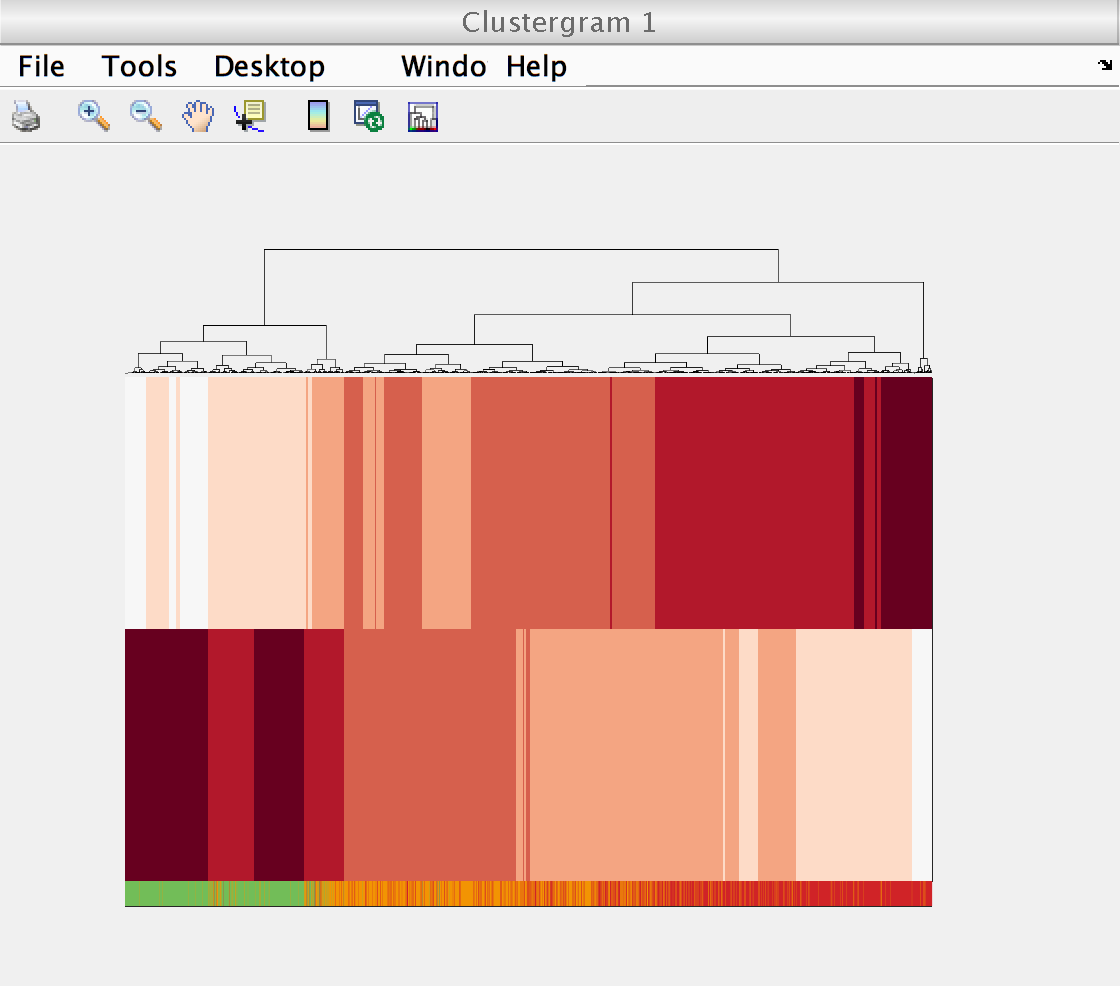

term = time; numCluster = 3; plot_or_not = 1;
colors = [114 189 88;242 148 3;208 35 39]/255;
warning ('off','all');
cell_cluster(best_one,Cells,numCluster,plot_or_not,term,colors);

#### 2 Visualize the cells by performing t-SNE on the aggregated epigenomic data obtained by scAI

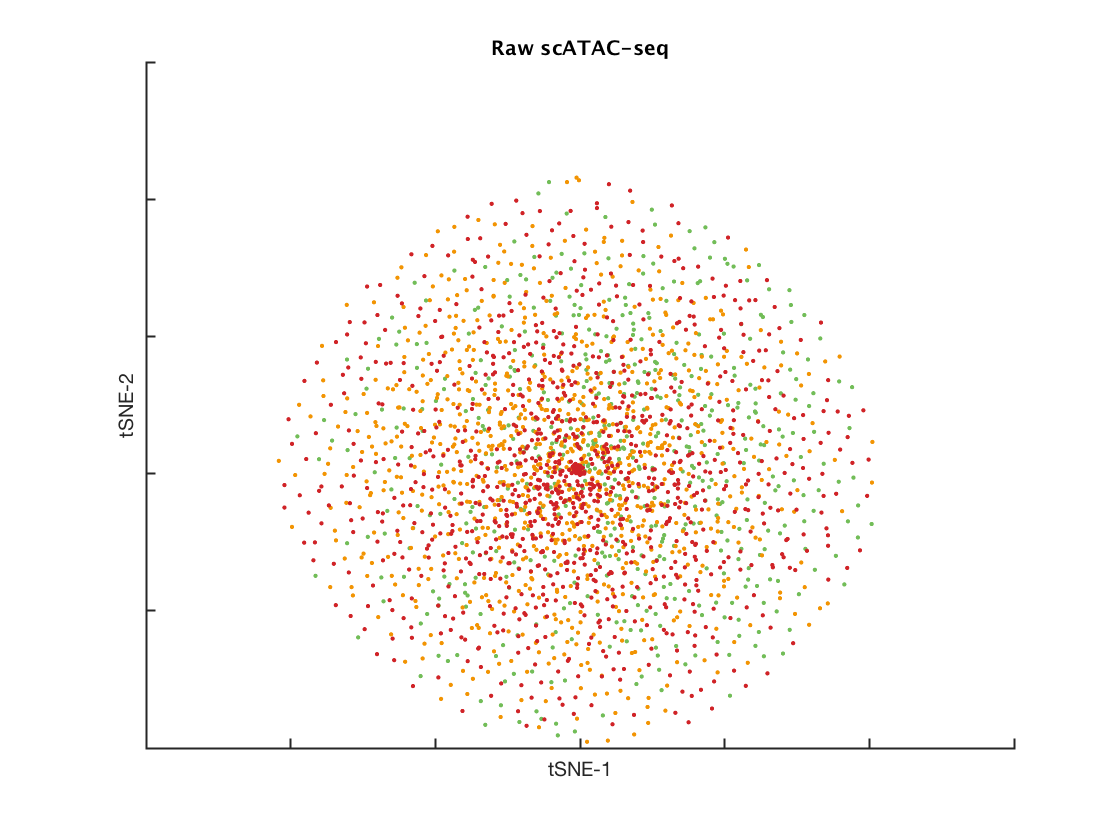

X2a = generate_aggregated_matrix(X2,best_one);
method = 'tSNE';
cell_coords1 = reducedDims(X2,Cells,method);
title_name = 'Raw scATAC-seq';
clust = [];
cellVisualizaiton(cell_coords1,clust,term,colors,title_name,method);

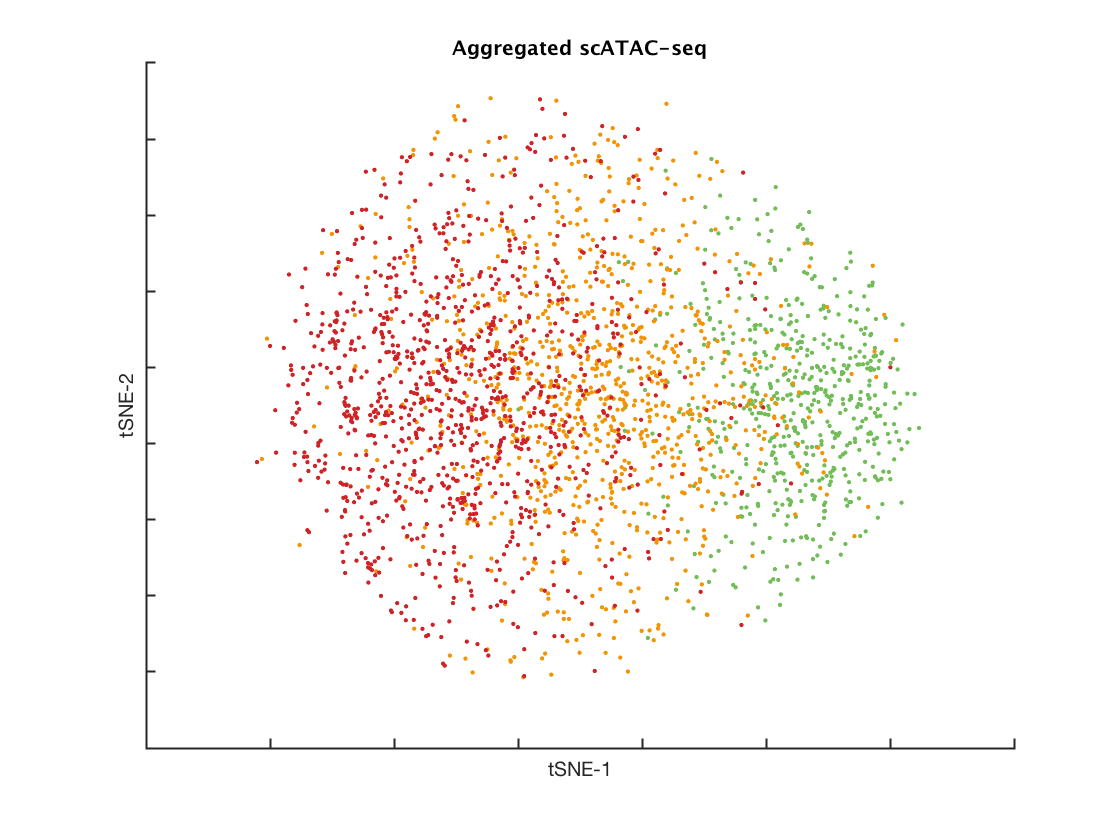

cell_coords2 = reducedDims(X2a,Cells,method);
title_name = 'Aggregated scATAC-seq';
clust = [];
cellVisualizaiton(cell_coords2,clust,term,colors,title_name,method);

#### 3 Identify component specific markers

W1 = best_one.W1; W2 = best_one.W2; H = best_one.H;

Identify factor specific genes

[factor_genes, factor_topgenes] = identifyFactorMarkers(X1,W1,H,Genes);

Plot the rank of marker genes, which are given by the user or use top genes of each factor.

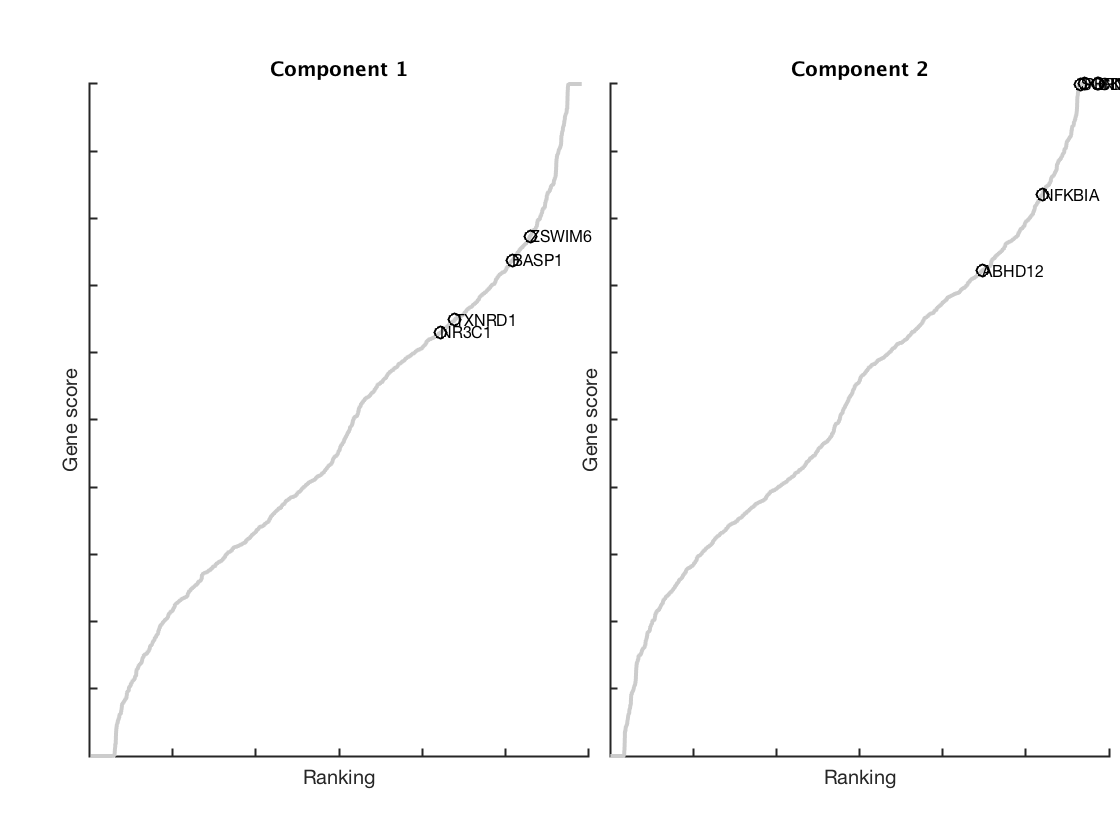

marker_genes = {'ZSWIM6','BASP1','TXNRD1','NR3C1','CKB','ABHD12','CDH16',...
    'NFKBIA','PER1','SCNN1A'};
top_per = 0.5;
featureRankingPlot(W1,Genes,marker_genes,[],[],top_per);

Identify factor specific loci

[factor_loci, factor_toploci] = identifyFactorMarkers(X2a,W2,H,Loci);

#### 4 Identify regulatory relationships

This procedure includes two steps. The first step is to find cis-regulatory elements in the Promoter and Enahncer regions of marker genes. The candidate loci may be bounded by TFs which can regulate marker genes. The second step is used to detect trans-acting TFs.

Search for regions of marker genes

system_used = 'Mac'; species = 'human';
Regions = search_gene_loci(marker_genes,system_used,species);

Identify marker genes with high correlation between expression levels and accessibility of their regulatory regions

Z = best_one.Z; repeat = 10; H_cutoff = 0.5; bin = 500000;
[relationships,regulatory] = identify_interaction(X1,X2,Z,s,repeat,Genes,...
    Loci,H,H_cutoff,marker_genes,Regions,bin,factor_genes,factor_loci);  

Identify motifs by ChromVAR

[motifs_database,motif_matrix] = run_chromVAR(ATAC,Loci,system_used);


Loading required package: GenomicRanges
Loading required package: stats4
Loading required package: BiocGenerics
Loading required package: parallel

Attaching package: ‘BiocGenerics’

The following objects are masked from ‘package:parallel’:

    clusterApply, clusterApplyLB, clusterCall, clusterEvalQ,
    clusterExport, clusterMap, parApply, parCapply, parLapply,
    parLapplyLB, parRapply, parSapply, parSapplyLB

The following objects are masked from ‘package:stats’:

    IQR, mad, sd, var, xtabs

The following objects are masked from ‘package:base’:

    anyDuplicated, append, as.data.frame, basename, cbind, colMeans,
    colnames, colSums, dirname, do.call, duplicated, eval, evalq,
    Filter, Find, get, grep, grepl, intersect, is.unsorted, lapply,
    lengths, Map, mapply, match, mget, order, paste, pmax, pmax.int,
    pmin, pmin.int, Position, rank, rbind, Reduce, rowMeans, rownames,
    rowSums, sapply, setdiff, sort, table, tapply, union, unique,
    unsplit, which, which.max, 

Identify TFs which regulate target genes by nonnegative least squares

[Target,allTFs] = identify_regulatory(RNA,H,motifs_database,motif_matrix,...
    relationships);

Plot the rank of marker loci, which are given by the user or use the top loci of each factor, and the enriched motifs are used to label the loci. Here, we plot the rank of loci, to which the TFs of marker genes are bounded.

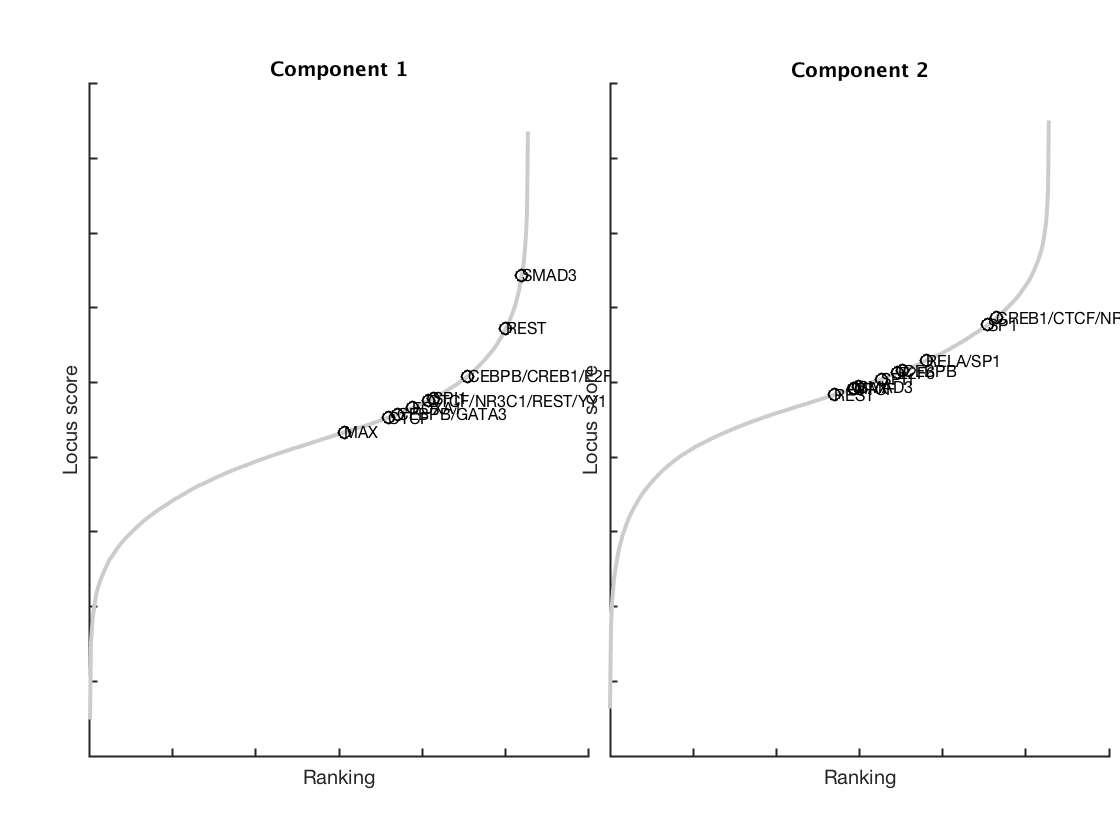

table_name = 'curatedTF_targets_A549'; 
tissue = 'lung';
[marker_loci,marker_motifs,gene_motifs] = extract_loci(Loci,marker_genes,...
    allTFs,table_name,tissue);
featureRankingPlot(W2,Loci,marker_loci,marker_motifs,[],top_per);

Validate the regulatory relationships according to database

[validate_relationships,validate_Relationships,fc,FC,pval,Pval] = ...
    validate_regulatory(Target,marker_genes,allTFs,table_name,tissue);

Plot the regulatory relationships between TFs and target marker gene

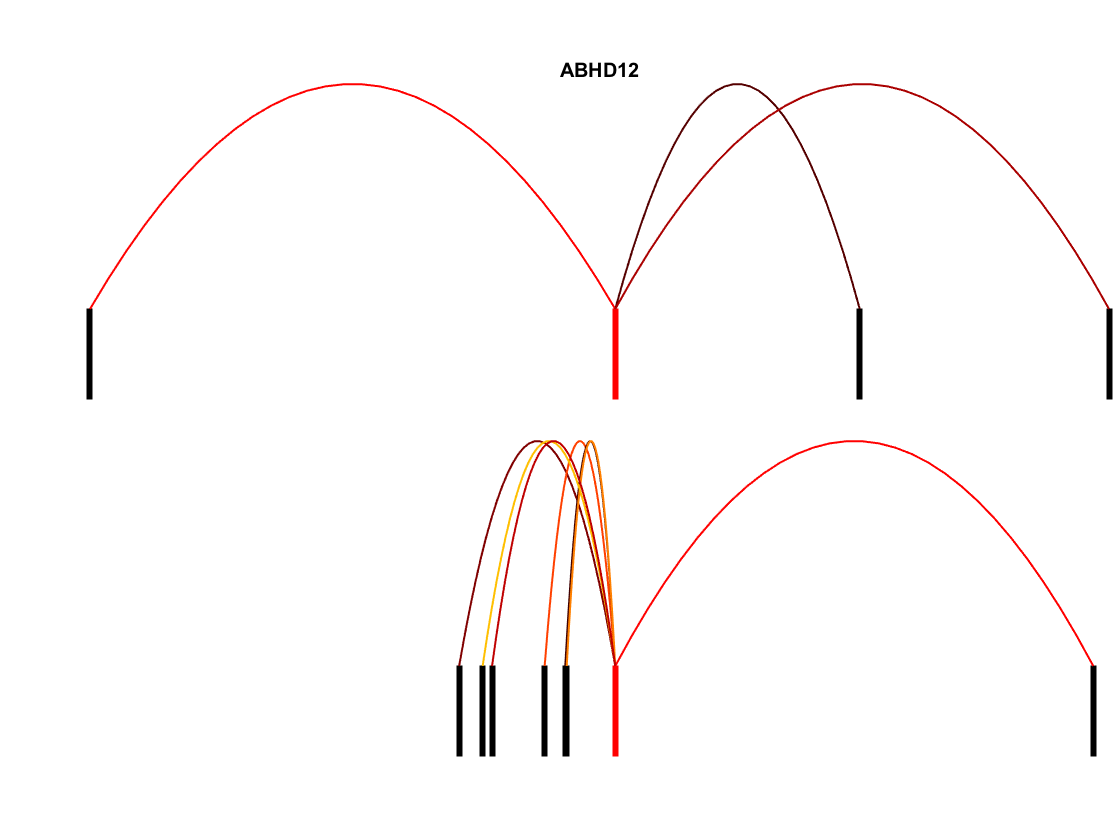

focus_markers = {'ABHD12'};
plot_regulatory(Target,focus_markers)

#### 5 Visualize markers alongsize the cells in two-dimensions using VscAI

system_used = 'Mac';
[sample_coords,factor_coords] = getEmbeddings(RNA,ATAC,marker_genes,...
    marker_loci,best_one,system_used);

The best seed is 5
Loading required package: ggplot2
Loading required package: cowplot

Attaching package: ‘cowplot’

The following object is masked from ‘package:ggplot2’:

    ggsave

Loading required package: Matrix
Warning messages:
1: package ‘ggplot2’ was built under R version 3.5.2 
2: package ‘cowplot’ was built under R version 3.5.2 
3: package ‘Matrix’ was built under R version 3.5.2 

Attaching package: ‘swne’

The following object is masked from ‘package:Seurat’:

    ExtractField

Initial stress        : 0.00000
stress after  10 iters: 0.00000, magic = 0.342


Visualize marker genes across all cells

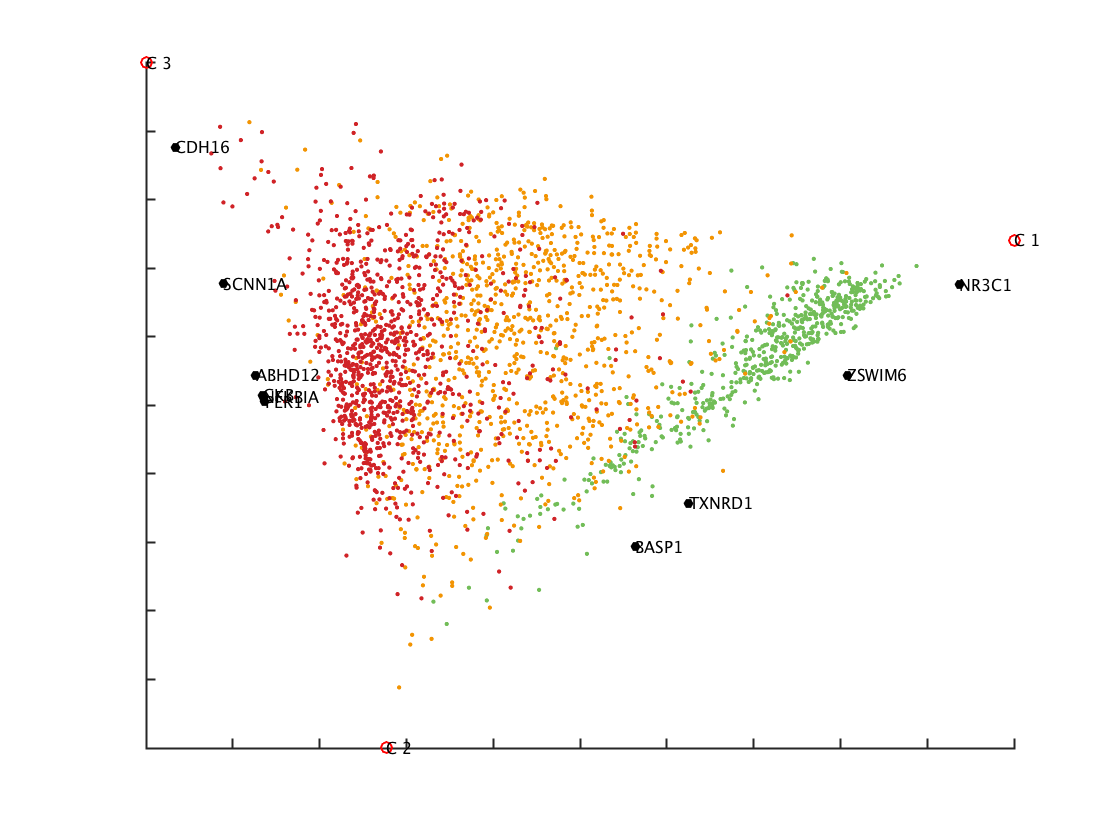

marker_genes_coords = readtable('./intermediateFiles/marker_coords_X1.txt',...
    'ReadRowNames',1);
VscAIplot(sample_coords,factor_coords,marker_genes_coords,[],[],clust,term,...
    colors);

Visualize chromatin regions of marker loci alongside the cells

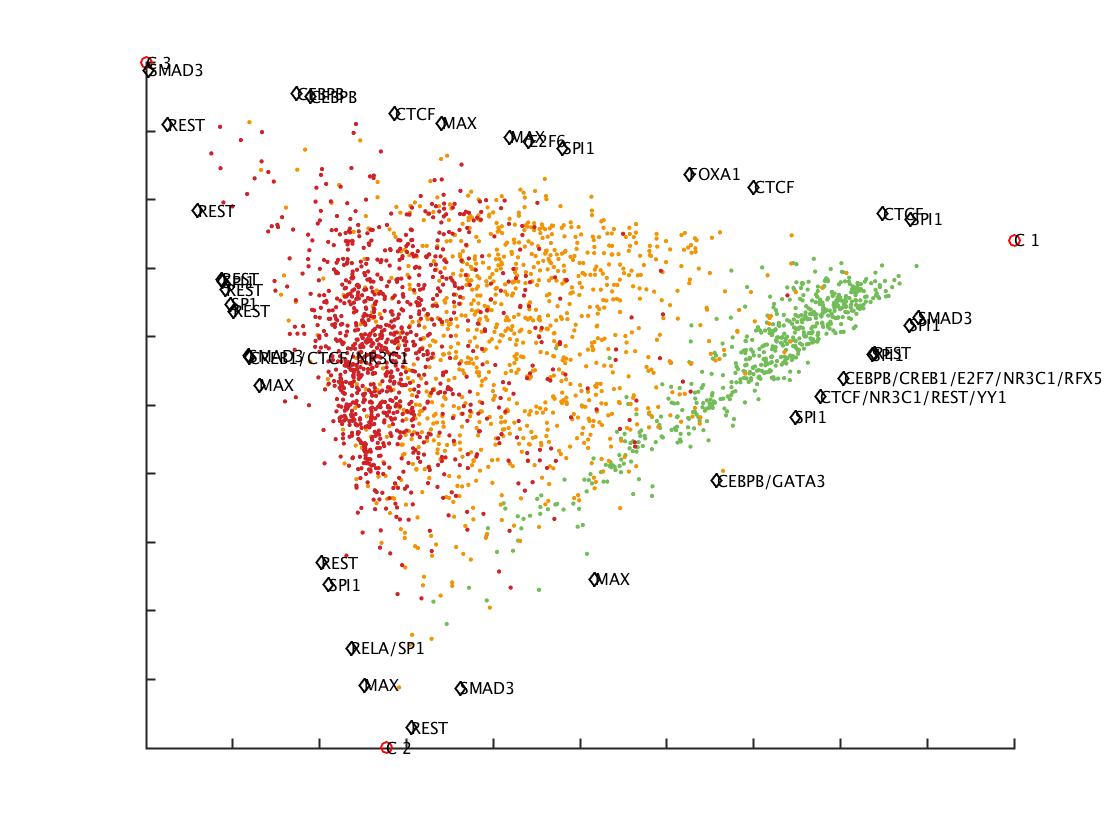

marker_loci_coords = readtable('./intermediateFiles/marker_coords_X2.txt',...
    'ReadRowNames',1);
VscAIplot(sample_coords,factor_coords,[],marker_loci_coords,...
    marker_motifs,clust,term,colors)